## Lab3.10

(a)论证：计算每个ak都需要N+1次复数乘法和N-1次复数加法

复数乘法：(n=0)~(n=N-1)共进行N次复数乘法，外面的1/N与求和所得再进行1次复数乘法，共N+1次。

复数加法：求和项为(n=0)~(n=N-1)，共进行N-1次复数加法。

计算DTFS需要2N^2次运算。

(b)记录使用dtft算法进行傅里叶级数计算所需时间。


dtfscomps = [0 0 0 0 0]
%分段计算N=8，32，64，128，256时利用dtft算法所需时间
t1 = clock;
N=8;
x = (0.9).^[0:N-1];
x = dtfs(x,0);
t2 = clock;
dtfscomps(1)=etime(t2,t1) %返回秒数

t1 = clock;
N=32;
x = (0.9).^[0:N-1];
x = dtfs(x,0);
t2 = clock;
dtfscomps(2)=etime(t2,t1)

t1 = clock;
N=64;
x = (0.9).^[0:N-1];
x = dtfs(x,0);
t2 = clock;
dtfscomps(3)=etime(t2,t1)

t1 = clock;
N=128;
x = (0.9).^[0:N-1];
x = dtfs(x,0);
t2 = clock;
dtfscomps(4)=etime(t2,t1)

t1 = clock;
N=256;
x = (0.9).^[0:N-1];
x = dtfs(x,0);
t2 = clock;
dtfscomps(5)=etime(t2,t1)


(c)使用fft计算DTFS系数，与(b)中速度进行对比。

%记录fft计算DTFT系数所用时间
fftcomps = [0 0 0 0 0]
t1 = clock;
N=8;
x = (0.9).^[0:N-1];
x = fft(x,0);
t2 = clock;
fftcomps(1)=etime(t2,t1)

t1 = clock;
N=32;
x = (0.9).^[0:N-1];
x = fft(x,0);
t2 = clock;
fftcomps(2)=etime(t2,t1)

t1 = clock;
N=64;
x = (0.9).^[0:N-1];
x = fft(x,0);
t2 = clock;
fftcomps(3)=etime(t2,t1)

t1 = clock;
N=128;
x = (0.9).^[0:N-1];
x = fft(x,0);
t2 = clock;
fftcomps(4)=etime(t2,t1);

t1 = clock;
N=256;
x = (0.9).^[0:N-1];
x = fft(x,0);
t2 = clock;
fftcomps(5)=etime(t2,t1);
%对比fft计算所需时间与dtft计算所需时间
figure;

nx = [8 32 64 128 256];
stem(nx,dtfscomps);
hold on
stem(nx,fftcomps,'r','*');
legend('dtfs','fft');
xlabel('n');
ylabel('t');

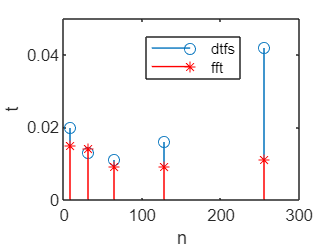

结论：由图可知，N较小时，fft算法和(b)中算法所耗时间相似。N较大时，fft所耗时间显著低于(b)中算法所耗时间。

(d)

Ny的基波周期为N。

为了实现此运算，需要n变量的N次循环嵌套r变量的N次循环，时间复杂度为O(N^2)。

(e)计算题目所给两信号的周期卷积，并画出。 

close all,clear all,clc;
%从x,h中取出一个周期
N = 40;
x = (0.9).^[0:N-1];
h = (0.5).^[0:N-1];
%计时计算卷积
t1 = clock;
y = conv([x x],h)
t2 = clock;
f40c = etime(t2,t1);
figure;
stem(0:N-1,y(1:N));
xlabel('n');
ylabel('y[n]');

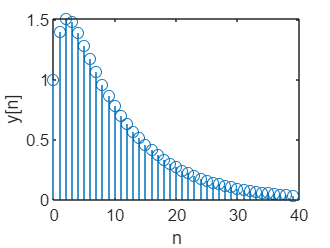

结论：y[n]如图。

(f)令N=80，重复(e).

%从x,h中取出一个周期
N = 80;
x = (0.9).^[0:N-1];
h = (0.5).^[0:N-1];
%计时计算卷积
t1 = clock;
y0 = conv([x x],h);
t2 = clock;
f80c = etime(t2,t1)
figure;
stem(0:N-1,y0(1:N));
xlabel('n');
ylabel('y[n]');

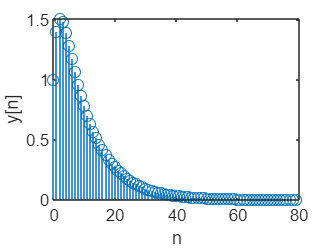

(g)计算x，h的DTFS记为ak,bk，两者进行卷积求得ck，求其傅里叶合成所得y1，比较y1是否与x，h直接卷积求得的y相同。

%从x,h中取出一个周期
N = 40;
x = (0.9).^[0:N-1];
h = (0.5).^[0:N-1];
%求x，h的DTFS,二者卷积得ck
t1=clock;
ak = fft(x)/N;
bk = fft(h)/N
ck = N*ak.*bk;       %??
%由ck傅里叶合成求解y1
y1 = ifft(ck)*N;
t2=clock;
f40f = etime(t2,t1);
figure;
stem(1:N,y1(1:N))
hold on
stem(1:N,y(1:N),'r','*')
legend('g题求得y[n]','e题求得y[n]');

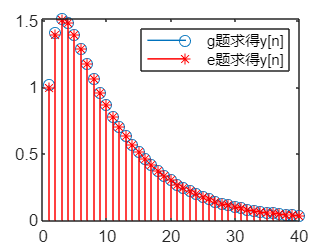

结论：由图可知，两题求得y[n]近似相等。

(h)

%从x,h中取出一个周期
N = 80;
x = (0.9).^[0:N-1];
h = (0.5).^[0:N-1];
%求x，h的DTFS,二者卷积得ck
t1=clock;
ak = fft(x)/N;
bk = fft(h)/N
ck = N*ak.*bk;       %??
%由ck傅里叶合成求解y1
y2 = ifft(ck)*N;
t2=clock;
f80f = etime(t2,t1)
figure;
stem(1:N,y2(1:N))
hold on
stem(1:N,y0(1:N),'r','*')
legend('h题求得y[n]','f题求得y[n]');

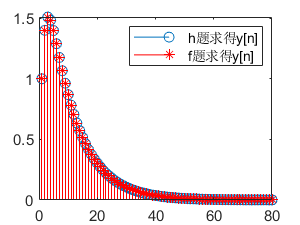

结论：由图可知，两题求得y[n]近似相等。

(i)比较N=40和N=80情况差别，并判断对每个N值，哪种方法高效。

f40c/f40f;

`ans = 5.1000`

f80c/f80f;

`ans = 0.8261`

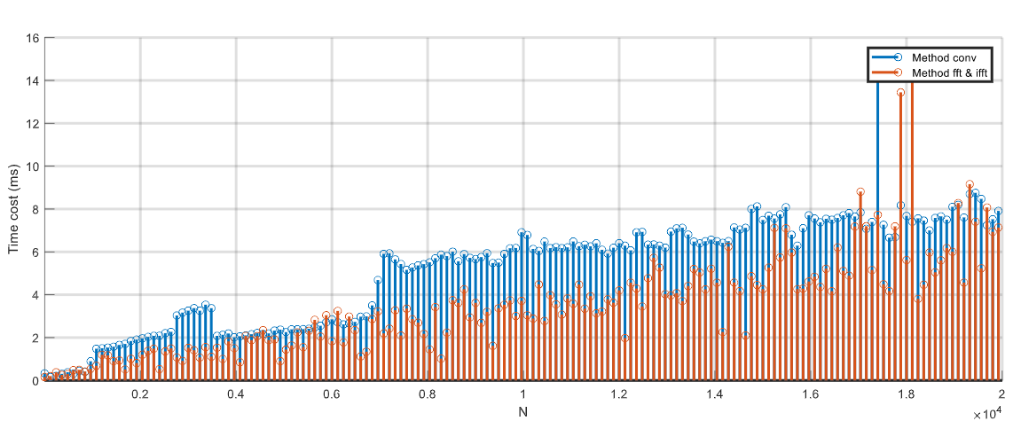

结论：N=40时，fft显著快于conv；N=80时，fft略低于conv。由网上的fft和conv对于每个N的值对比图像得，对于每个N，大部分情况为fft更高效，N>80时选择fft。

function a = dtfs(x,n_init)
N = length(x);
a = zeros(1,N);
for k=0:N-1
    for n=0:N-1
        a(k+1) = a(k+1)+x(n+1)*exp(-i*k*(2*pi/N)*(n_init+n));
    end
    a(k+1) = 1/N*a(k+1);
end
end
